clear all
close all


## Load Dataset

T = readtable('asu_solar_dataset.csv');

X = table2array(T(:,1:10));
classes = ["Degraded" "Shaded" "Soiled" "SC" "STC"];
y = table2array(T(:,11:15));
Y = onehotdecode(y,classes,2);
rng(1);

Y = categorical(Y);

[m,n] = size(X) ;
P = 0.70 ;
idx = randperm(m) ;
trainx = X(idx(1:round(P*m)),:) ; 
trainy = Y(idx(1:round(P*m)));
testx = X(idx(round(P*m)+1:end),:) ;
testy = Y(idx(round(P*m)+1:end));


[coeff,scoreTrain,~,~,explained,mu] = pca(trainx);

idx = 4;%find(cumsum(explained)>80,1);
scoreTrain80 = scoreTrain(:,1:idx);

[coeff,scoreTest,~,~,explained,mu] = pca(testx);

colmin = min(scoreTrain80);
colmax = max(scoreTrain80);
%trainx = rescale(scoreTrain80,"InputMin",colmin,"InputMax",colmax);
trainx = scoreTrain80;


scoreTest80 = (testx-mu)*coeff(:,1:idx);
colmin = min(scoreTest80);
colmax = max(scoreTest80);
%testx = rescale(scoreTest80,"InputMin",colmin,"InputMax",colmax);
testx = scoreTest80;

inputSize = size(trainx,2);
numClasses = 5;

## Build NN:

### hybrid quantum-classical 

layers_quantum_classical = [
    featureInputLayer(inputSize,Normalization="rescale-zero-one")
    PQCLayer4
    fullyConnectedLayer(numClasses)
    softmaxLayer];

### classical 

layers_classical = [
    featureInputLayer(inputSize,Normalization="zscore") %zscale
    fullyConnectedLayer(8) %16
    layerNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];


### Options

options = trainingOptions("sgdm", ...
    MiniBatchSize=20, ...
    InitialLearnRate=0.1, ...
    Momentum=0.9, ...
    ExecutionEnvironment="cpu", ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Classical Train NN

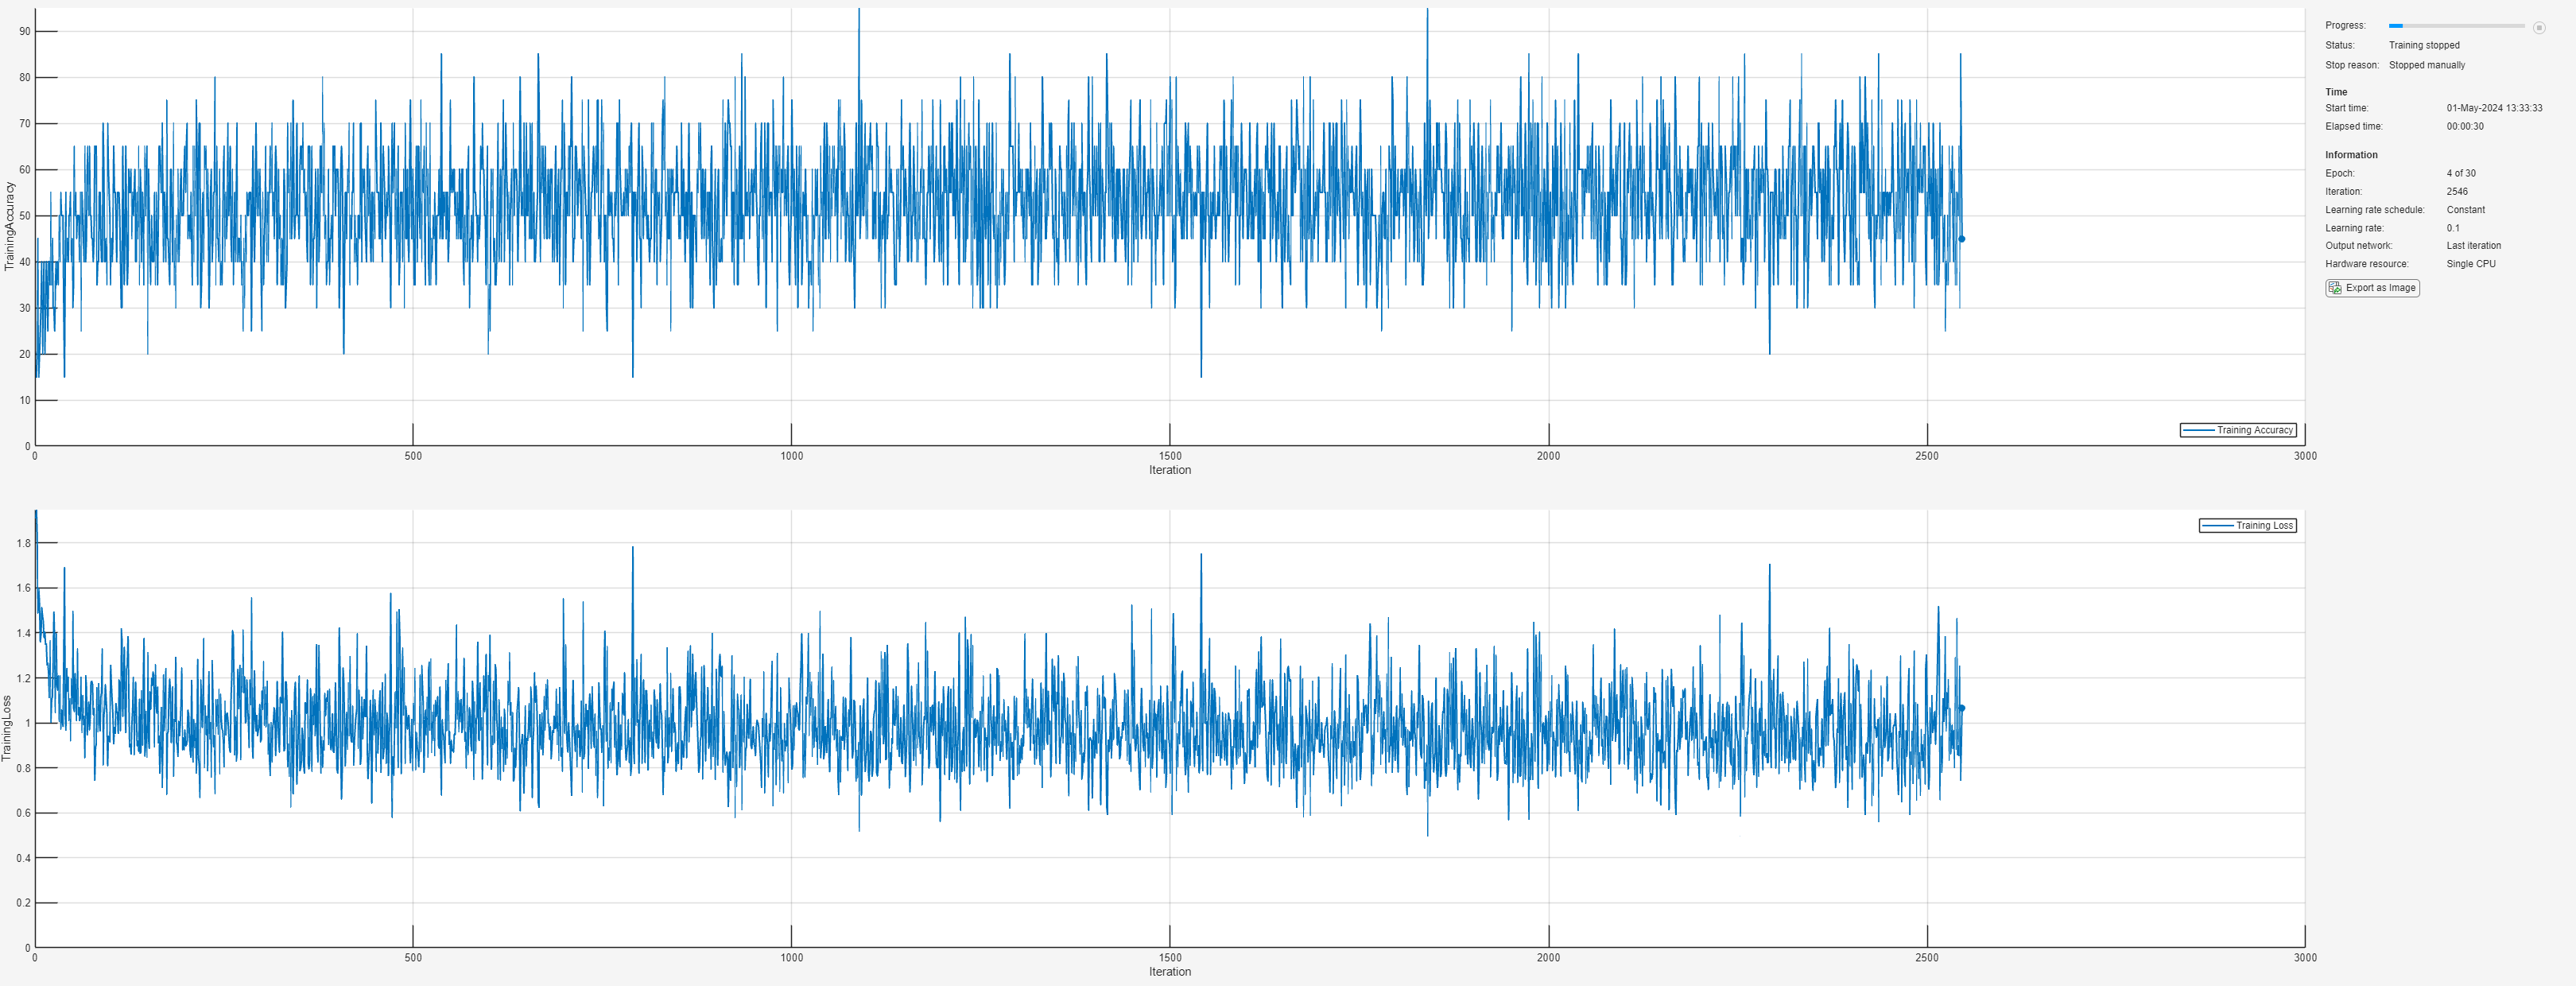

net_c = trainnet(trainx,trainy,layers_classical,"crossentropy",options);

## Test

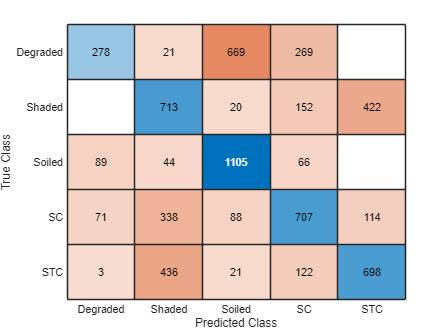

predictedLabels = predict(net_c,testx);
Y_predict = onehotdecode(predictedLabels,classes,2);
confusionchart(testy,Y_predict)

accuracy = mean(testy==Y_predict)

accuracy = 0.5431

## Quantum Classical Train NN

net_q_c = trainnet(trainx,trainy,layers_quantum_classical,"crossentropy",options);

Error using trainnet (line 46)
Invalid network.

Caused by:
    Layer 'PQCLayer4': Error using the predict function in layer PQCLayer4. The function threw an error and could not be executed.
        Index in position 1 exceeds array bounds. Index must not exceed 3.
        
        Error in PQCLayer4>computeZ (line 180)
            x4 = X(4,:);
        
        Error in 

## Test

predictedLabels = predict(net_q_c,testx);
Y_predict = onehotdecode(predictedLabels,classes,2);
confusionchart(testy,Y_predict)
accuracy = mean(testy==Y_predict)